## **Methods in Computational Neuroscience 2024**

## **Final Project**

## **Investigating the behavioral and neural aftermath of barrier presentation.**

Could we detect differences between trials with/out barriers? 

If so, where and when can we detect such differences? Also, could we decode based on the neural firing and classify whether a given trial is presented with barriers?

## **Data Visualization**

### **1) Delay duration histogram**

% load data
load("mazeJ0918Simple3.mat");

% number of trials
nTrials = size(R, 2);

% get delay duration values
total_delays = zeros(nTrials, 1);
for i=1:nTrials
    total_delays(i) = R(i).delayDur;
end

median_delay = median(total_delays)

median_delay = 648

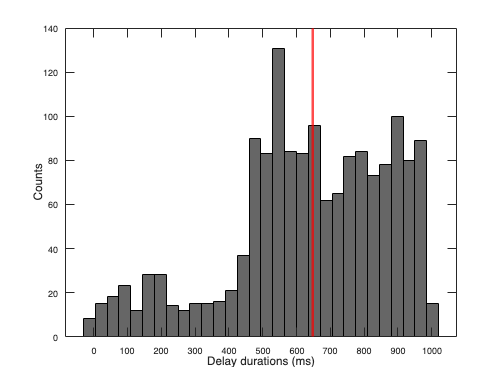

% plot
figure;
histogram(total_delays, 30, 'FaceColor','k')
xline(median_delay, 'Color','r', 'LineWidth',3)
xlabel("Delay durations (ms)", FontSize=13)
ylabel("Counts", FontSize=13)

Varying degrees of delay durations shown in this histogram.

For the most of the subsequent analyses, we will be using trials with at least 400ms of delay duration. 

### **2) RT for each condition**

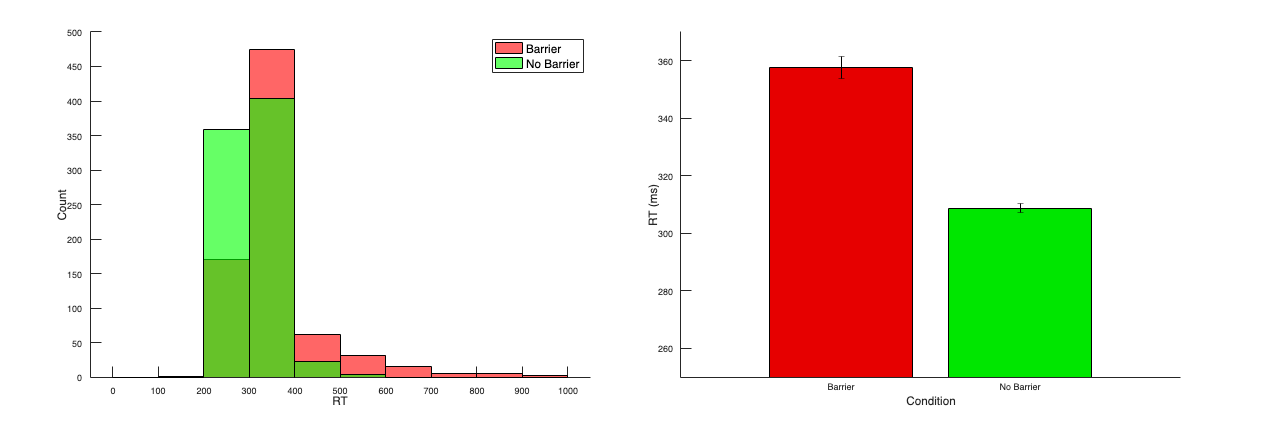

% get RT values
total_RTs = zeros(nTrials, 1);
cond_list = zeros(nTrials, 1); %% 1-> barriers, 2-> no barriers
for i=1:nTrials
    total_RTs(i) = R(i).RT;
    cond_list(i) = R(i).mazeCategory;
end

all_trials = 1:nTrials;
barrier_trials = all_trials(cond_list == 1);
no_barrier_trials = all_trials(cond_list == 2);

% by conditions
barrier_RT = total_RTs(cond_list == 1);
no_barrier_RT = total_RTs(cond_list == 2);
barrier_RT_mean = mean(barrier_RT);
no_barrier_RT_mean = mean(no_barrier_RT);

% bootstrap
n_runs = 100;
barrier_sem = bootstrap(barrier_RT, n_runs);
no_barrier_sem = bootstrap(no_barrier_RT, n_runs);

% plot
figure("Position", [0 0 1500 500]);
tiledlayout(1,2);

nexttile;
hold on

edges = 0:100:1000;
histogram(barrier_RT, edges, "FaceColor", "r");
histogram(no_barrier_RT, edges, "FaceColor", "g");
legend({"Barrier" "No Barrier"}, FontSize=13)
xlabel("RT", FontSize=13)
ylabel("Count", FontSize=13)
hold off

nexttile;
hold on

X = categorical({'Barrier', 'No Barrier'});
X = reordercats(X,{'Barrier', 'No Barrier'});

b = bar(X, [barrier_RT_mean, no_barrier_RT_mean]);
b.FaceColor = 'flat';
b.CData(1,:) = [0.9,0,0]; 
b.CData(2,:) = [0,0.9,0];

er = errorbar(X, ...
    [barrier_RT_mean, no_barrier_RT_mean], ...
    [barrier_sem, no_barrier_sem], ...
    [barrier_sem, no_barrier_sem]);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

ylim([250,370]);
xlabel("Condition", FontSize=13)
ylabel("RT (ms)", FontSize=13)
hold off

As expected, barrier condition resulted in higher RT than no barrier condition. 

This shows the effect of barrier presentation, where monkeys took longer to plan out the movement compared to no barrier conditions. 

Also, RTs for the barrier conditions seem more variable than no barrier conditions based on the error bars. 

Error bars are plotted through bootstrapping. 

### **3) Hand trajectory**

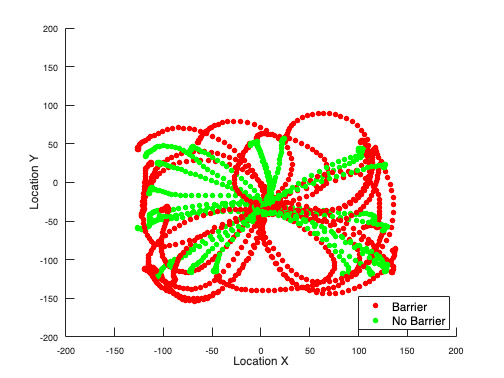

% get all the target locations
target_locs = zeros(nTrials, 2);
for i=1:nTrials
    target_locs(i,:) = R(i).targetXY;
end

% find unique target locations
uniq_target_locs = unique(target_locs, "rows");

figure;
hold on

for i=1:length(uniq_target_locs)
    % get current unique target location
    curr_target_loc = uniq_target_locs(i,:);
    % find corresponding trials for both conditions
    curr_barrier_ind = find(target_locs == curr_target_loc & cond_list == 1, 1, 'first');
    curr_no_barrier_ind = find(target_locs == curr_target_loc & cond_list == 2, 1, 'first');
    % get hand trajectory data
    curr_barrier_x = R(curr_barrier_ind).HAND.X;
    curr_barrier_Y = R(curr_barrier_ind).HAND.Y;
    curr_no_barrier_x = R(curr_no_barrier_ind).HAND.X;
    curr_no_barrier_Y = R(curr_no_barrier_ind).HAND.Y;

    % plot
    scatter(curr_barrier_x, curr_barrier_Y, "filled", "MarkerFaceColor", "r")
    scatter(curr_no_barrier_x, curr_no_barrier_Y, "filled", "MarkerFaceColor", "g")

end

xlabel("Location X", FontSize=13)
ylabel("Location Y", FontSize=13)
xlim([-200,200])
ylim([-200,200])
legend(["Barrier" "No Barrier"], "Location","southeast", "FontSize",13)
hold off

Here, we are plotting hand trajectories for both conditions (barrier / no barrier) for each target locations.

For the sake of visibility, we are plotting 2 trials per each target location. 

### **4) Raster plot (first 100 trials only)**

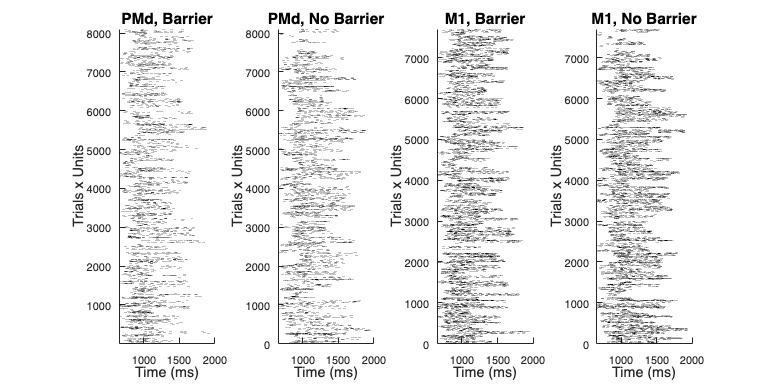

figure;
subplot(1, 4, 1);
plotRaster(R, 100, barrier_trials, 1);
title("PMd, Barrier", FontSize=14)

subplot(1, 4, 2);
plotRaster(R, 100, no_barrier_trials, 1);
title("PMd, No Barrier", FontSize=14)

subplot(1, 4, 3);
plotRaster(R, 100, barrier_trials, 2);
title("M1, Barrier", FontSize=14)

subplot(1, 4, 4);
plotRaster(R, 100, no_barrier_trials, 2);
title("M1, No Barrier", FontSize=14)

Here are 4 different rasterplots, looking at timepoints between target onset and go cue onset. 

Since there are numerous trials x units data, we are plotting only the first 100 trials per each condition. 

Based on these rasterplots, it is hard to say that there exists distinct neural firing patterns between PMd neurons and M1 neurons under different conditions. 

### **5) PSTH (for each condition)**

% first, get binned spike counts
timeBins = -100:10:400;
nTimeBins = length(timeBins)-1;
nUnits = 158;

data = binData(R, timeBins, "targetAppearsTime");

% filter for the delay duration > 400
selected_ind = total_delays > 400;
data = data(:,selected_ind,:);

% now into spikes/s
spike_data = data / 0.01;
% and smooth it over 30ms
smooth_spike_data = gaussFilt1(spike_data, 3);

% next, average over trials
selected_trials = all_trials(selected_ind);
total_IDs = zeros(1, length(selected_trials));
total_conds = zeros(1, length(selected_trials));
for i=1:length(selected_trials)
    total_IDs(i) = R(selected_trials(i)).conditionID;
    total_conds(i) = R(selected_trials(i)).mazeCategory;
end
uniq_IDs = unique(total_IDs);

% also get corresponding condition IDs
uniq_conds = zeros(length(uniq_IDs),1);
for i=1:length(uniq_IDs)
    uniq_conds(i) = R(uniq_IDs(i)).mazeCategory;
end

% new matrix for averaged data
avg_data = zeros(nTimeBins, length(uniq_IDs), nUnits); 

% for each condition ID
for i=1:length(uniq_IDs)
    % get corresponding trials
    curr_ID = uniq_IDs(i);
    curr_trial_idx = total_IDs == curr_ID;
    % average over trials
    curr_trial_data = smooth_spike_data(:,curr_trial_idx,:);
    avg_trial_data = mean(curr_trial_data,2);
    % save appropriately
    avg_data(:,i,:) = avg_trial_data;
end

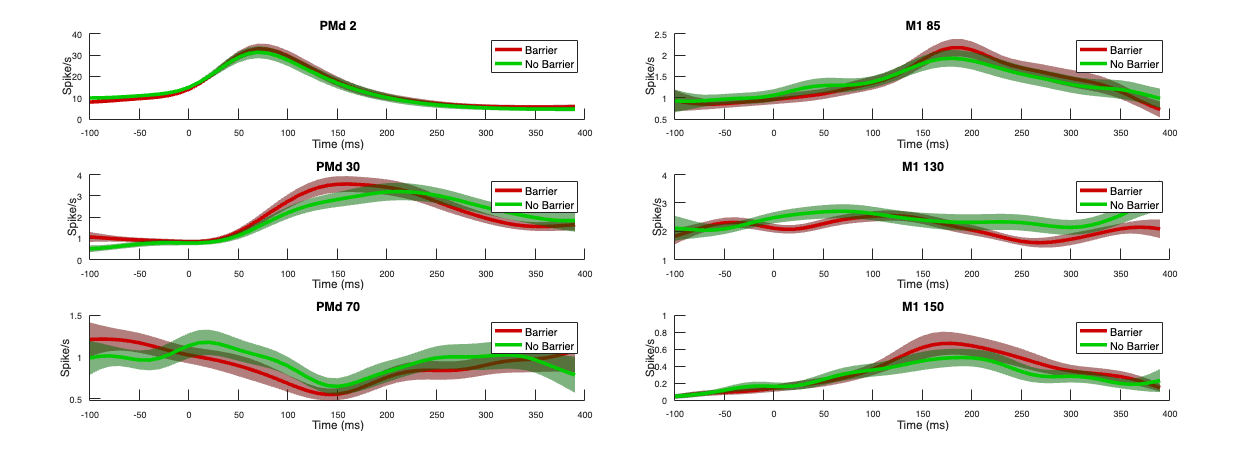

% 6 sample units
figure("Position",[0 0 1400 500]);
t = tiledlayout(3,2);

c_list = [[0.8,0,0]; [0,0.8,0]];
unit_label = ["PMd 2", "M1 85", "PMd 30", "M1 130", "PMd 70", "M1 150"];
cond_label = ["Barrier", "No Barrier"];
which_unit = [2, 85, 30, 130, 70, 150];

for u=1:length(which_unit)
    nexttile;
    hold on

    % for each condition
    for i=1:2
        % get corresponding data
        curr_data = avg_data(:,uniq_conds==i,which_unit(u));
    
        % plot PSTH w/ SEM
        curr_mean = mean(curr_data,2);
        curr_sem = std(curr_data,0,2)/sqrt(size(curr_data,2));
        x = timeBins(1:end-1);
        lower_SEM = curr_mean - curr_sem;
        upper_SEM = curr_mean + curr_sem;
        p = patch([x'; flip(x')], ...
              [lower_SEM; flip(upper_SEM)], ...
              c_list(i,:)*0.5, 'EdgeColor', 'none');
        p.FaceVertexAlphaData = 0.2;
        p.FaceAlpha = 'flat';
        p.HandleVisibility = "off";
        plot(x, curr_mean, 'Color', c_list(i,:), 'LineWidth',4,...
            'DisplayName',cond_label(i));
    end
    
    legend(FontSize=12);
    xlabel("Time (ms)", FontSize=13)
    ylabel("Spike/s", FontSize=13)
    title(unit_label(u), FontSize=14)
    hold off
end

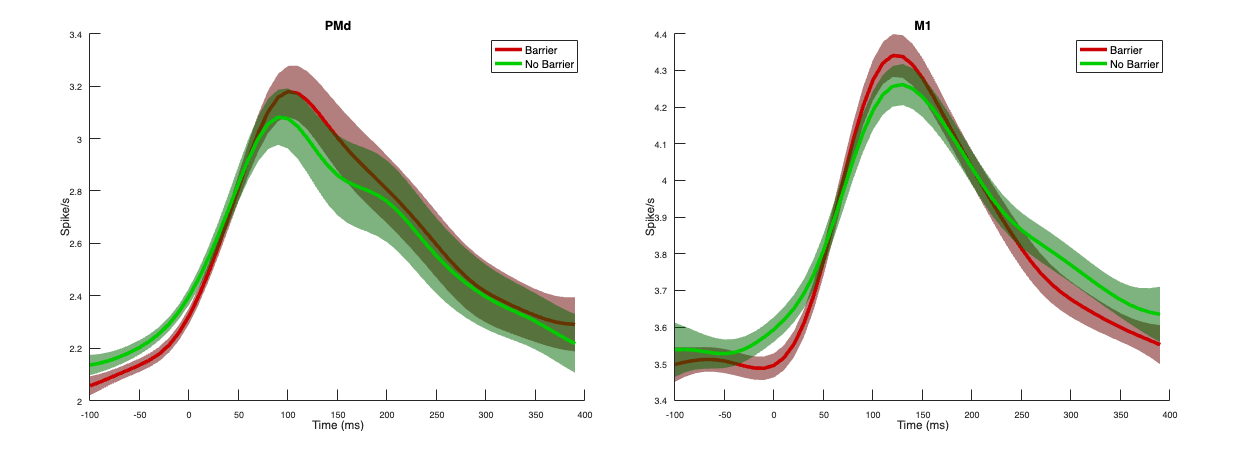

% plot PSTH for each condition averaged across trials & units
figure("Position",[0 0 1400 500]);
t = tiledlayout(1,2);

c_list = [[0.8,0,0]; [0,0.8,0]];
unit_label = ["PMd", "M1"];
cond_label = ["Barrier", "No Barrier"];
which_array = R(1).whichArray;

for c=1:2
    nexttile;
    hold on

    % for each condition
    for i=1:2
        % get corresponding data
        curr_data = avg_data(:,uniq_conds==i,which_array==c);
        % average over units
        curr_data = mean(curr_data, 3);
    
        % plot PSTH w/ SEM
        curr_mean = mean(curr_data,2);
        curr_sem = std(curr_data,0,2)/sqrt(size(curr_data,2));
        x = timeBins(1:end-1);
        lower_SEM = curr_mean - curr_sem;
        upper_SEM = curr_mean + curr_sem;
        p = patch([x'; flip(x')], ...
              [lower_SEM; flip(upper_SEM)], ...
              c_list(i,:)*0.5, 'EdgeColor', 'none');
        p.FaceVertexAlphaData = 0.2;
        p.FaceAlpha = 'flat';
        p.HandleVisibility = "off";
        plot(x, curr_mean, 'Color', c_list(i,:), 'LineWidth',4,...
            'DisplayName',cond_label(i));
    end
    
    legend(FontSize=12);
    xlabel("Time (ms)", FontSize=13)
    ylabel("Spike/s", FontSize=13)
    title(unit_label(c), FontSize=14)
    hold off
end

Here are the PSTHs for each neuronal type (PMd, M1), which each subplot showing two different conditions (with error bars representing SEM). 

Data is aligned to target onset time, and only the trials with delay periods longer than 400ms are included in PSTHs. 

Overall, there seems to be no significant differences in terms of firing patterns between PMd and M1 neurons. 

It is interesting to see that M1 neurons, although monkeys are trained to fixate during delay period, has similar, if not same, firing pattern to PMd neurons, which might illustrate their co-active properties. 

## **Trial-to-trial variability**

- Look at the Fano factor for trials with barriers and without barriers.

- Only include trials that has at least 400ms of delay duration

% settings
time_bins = -100:30:400;
all_units = 1:158;
which_array = R(1).whichArray;

% initialize matrix to save data
target_FF_data = {};
movement_FF_data = {};

% for each neuron type
for n=1:2
    % get current unit locs
    curr_n_array = all_units(which_array == n);
    curr_n_target_FF_data = zeros(length(time_bins), length(uniq_IDs), length(curr_n_array));
    curr_n_movement_FF_data = zeros(length(time_bins), length(uniq_IDs), length(curr_n_array));

    % for each condition
    for cond=1:length(uniq_IDs)

        % for each unit
        for u=1:length(curr_n_array)
            curr_unit = curr_n_array(u);
            curr_cond = uniq_IDs(cond);
            min_delay = 400;
            time_window = 200;

            % for each time bin
            for t=1:length(time_bins)
                % calculate the Fano factor
                [~, ~, curr_FF] = FanoFactor(R, curr_cond, curr_unit, min_delay, ...
                                             "targetAppearsTime", time_bins(t), time_window);
                curr_n_target_FF_data(t,cond,u) = curr_FF;

                [~, ~, curr_FF] = FanoFactor(R, curr_cond, curr_unit, min_delay, ...
                                             "moveOnsetTime", time_bins(t), time_window);
                curr_n_movement_FF_data(t,cond,u) = curr_FF;
            end

        end

    end

    % save data
    target_FF_data{n} = curr_n_target_FF_data;
    movement_FF_data{n} = curr_n_movement_FF_data;

end

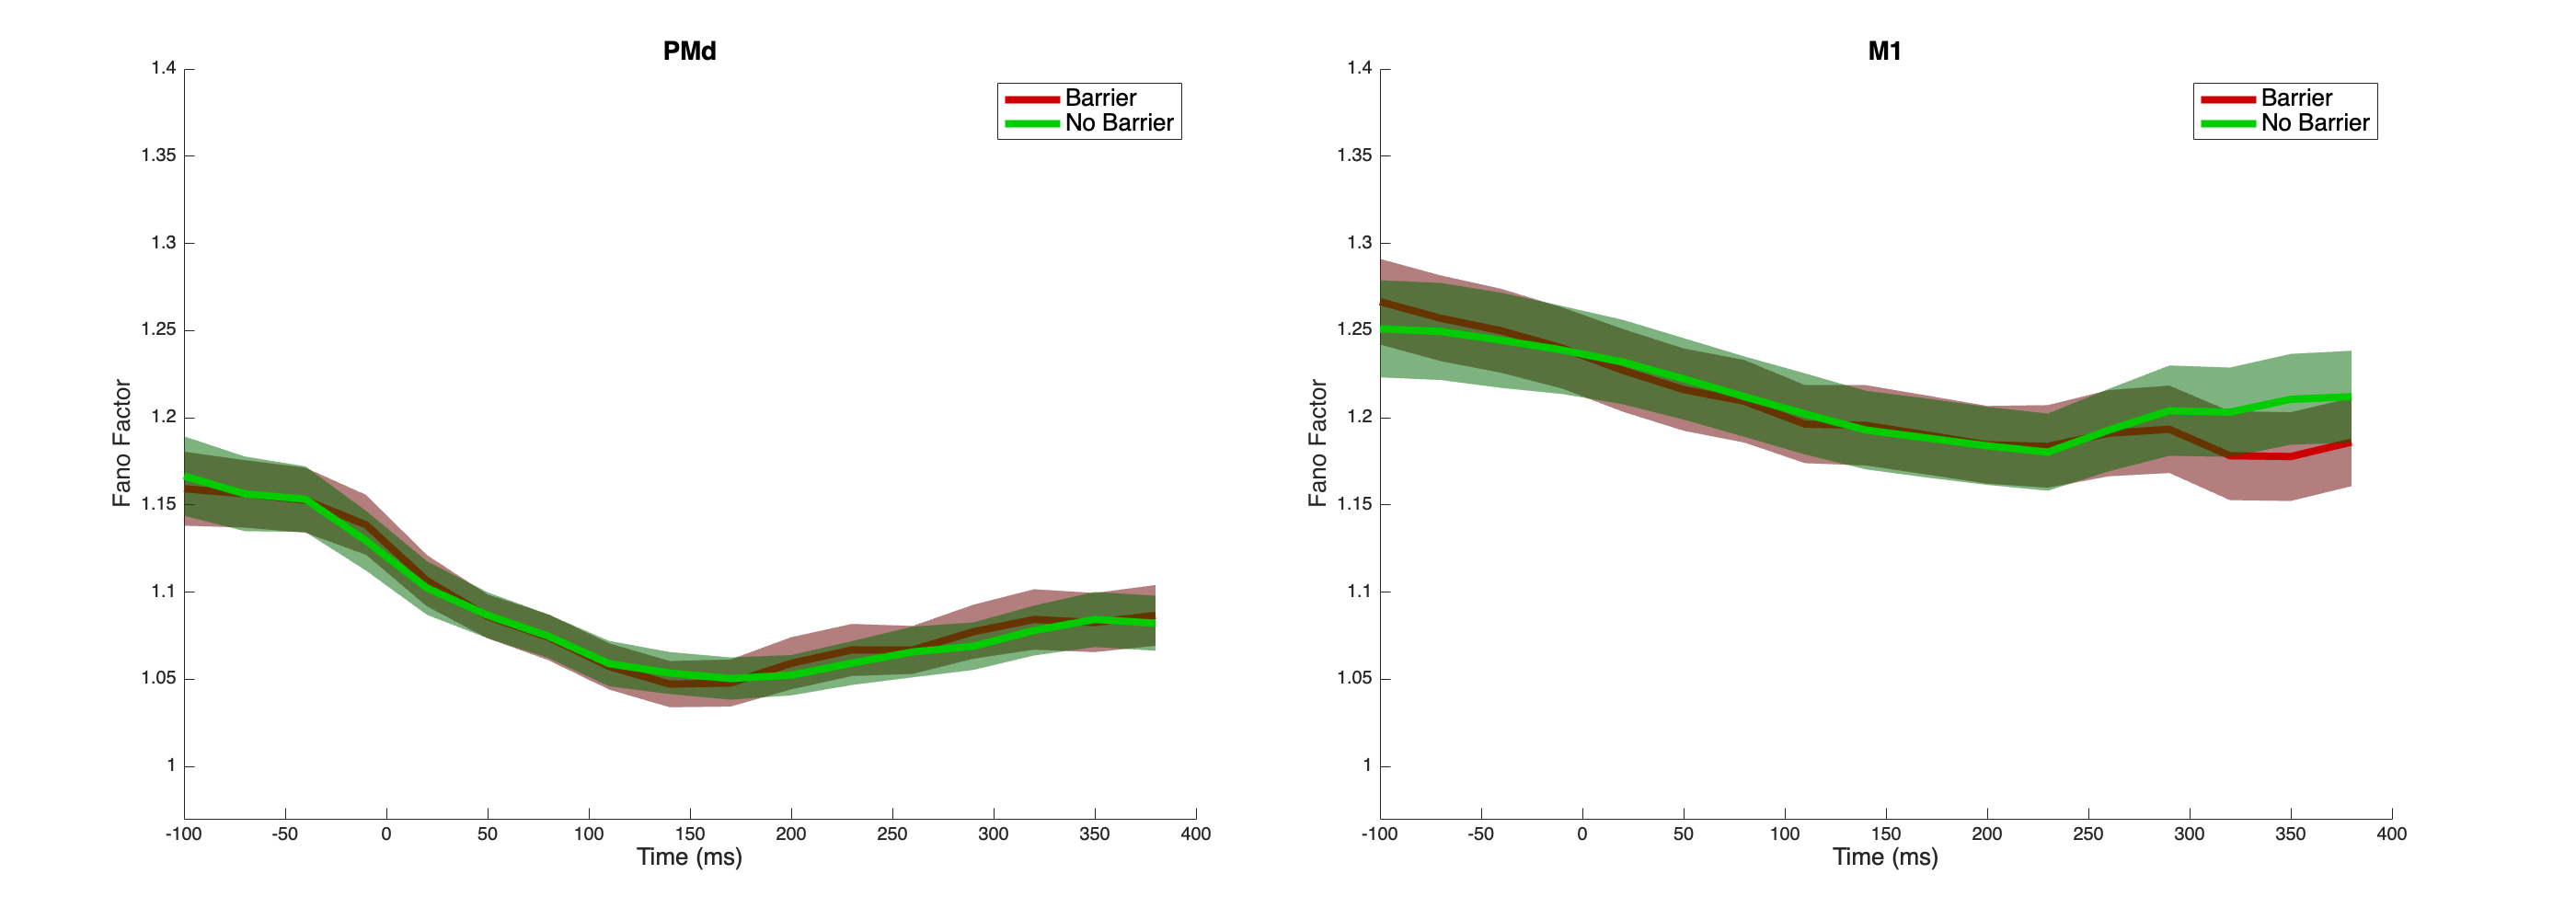

figure("Position",[0 0 1400 500]);
tiledlayout(1,2);

c_list = [[0.8,0,0]; [0,0.8,0]];
unit_label = ["PMd", "M1"];
cond_label = ["Barrier", "No Barrier"];

for n=1:2
    nexttile;
    hold on

    % load data
    curr_data = target_FF_data{n};
    
    for cond=1:2
        % get trial datas for given condition (barrier / no barrier)
        curr_IDs = uniq_conds == cond;
        curr_FF_data = curr_data(:,curr_IDs,:);

        % for NaN Fano factors, replace them with 1 assuming ideal
        % Poisson firing characteristics
        curr_FF_data(isnan(curr_FF_data))=1;

        % average across trials
        avg_FF_data = reshape(mean(curr_FF_data, 2), size(curr_FF_data,[1,3]));

        % plot with SEM
        curr_mean = mean(avg_FF_data,2);
        curr_sem = std(avg_FF_data,0,2) / sqrt(size(avg_FF_data,2));
        x = time_bins;
        lower_SEM = curr_mean - curr_sem;
        upper_SEM = curr_mean + curr_sem;
        p = patch([x'; flip(x')], ...
              [lower_SEM; flip(upper_SEM)], ...
              c_list(cond,:)*0.5, 'EdgeColor', 'none');
        p.FaceVertexAlphaData = 0.2;
        p.FaceAlpha = 'flat';
        p.HandleVisibility = "off";
        plot(x, curr_mean, 'Color', c_list(cond,:), 'LineWidth',4,...
            'DisplayName',cond_label(cond));
    end

    xlabel("Time (ms)", "FontSize", 13);
    ylabel("Fano Factor", "FontSize", 13);
    ylim([0.97 1.4]);
    legend("FontSize", 13);
    title(unit_label(n), "FontSize", 14);

end

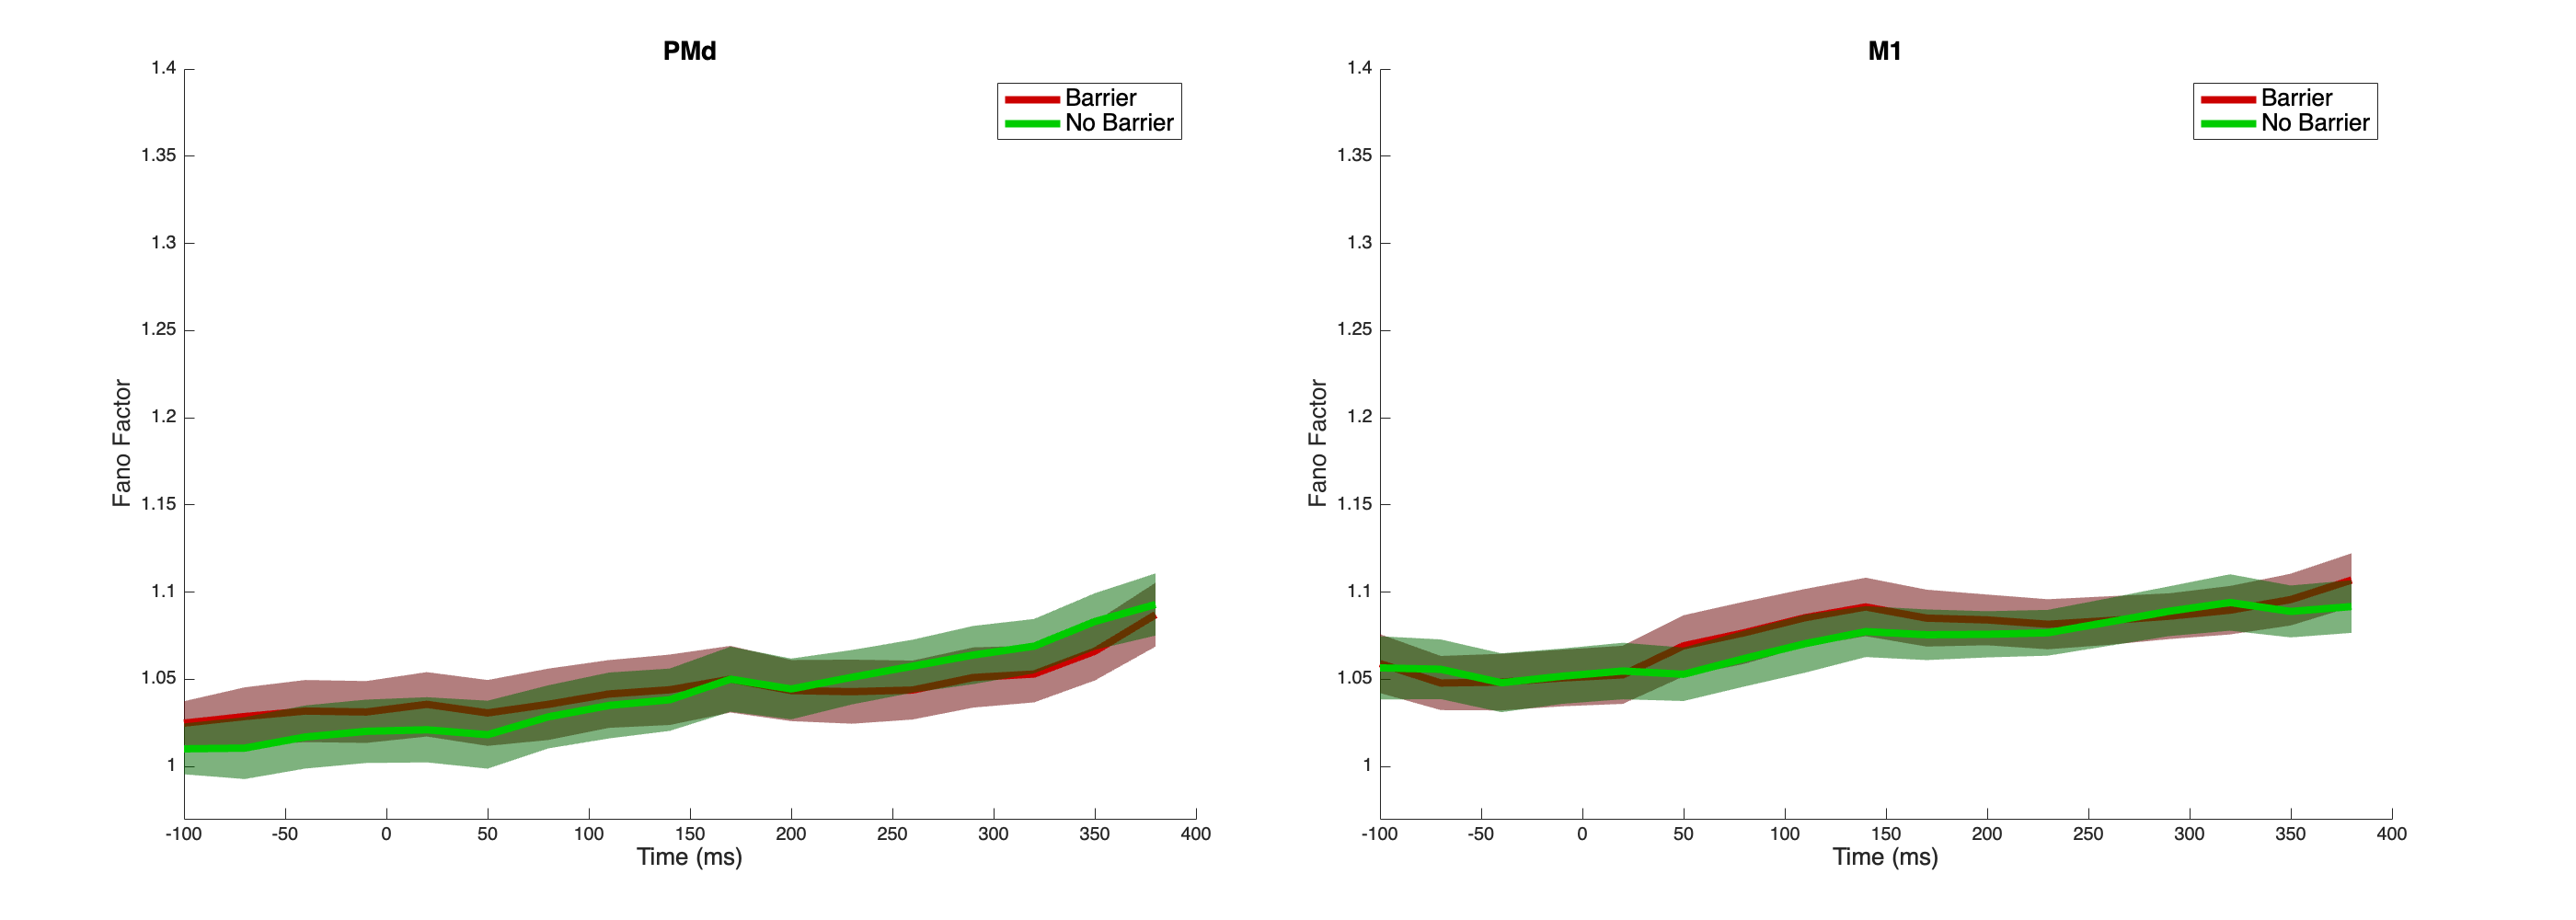

figure("Position",[0 0 1400 500]);
tiledlayout(1,2);

c_list = [[0.8,0,0]; [0,0.8,0]];
unit_label = ["PMd", "M1"];
cond_label = ["Barrier", "No Barrier"];

for n=1:2
    nexttile;
    hold on

    % load data
    curr_data = movement_FF_data{n};
    
    for cond=1:2
        % get trial datas for given condition (barrier / no barrier)
        curr_IDs = uniq_conds == cond;
        curr_FF_data = curr_data(:,curr_IDs,:);

        % for NaN Fano factors, replace them with 1 assuming ideal
        % Poisson firing characteristics
        curr_FF_data(isnan(curr_FF_data))=1;

        % average across trials
        avg_FF_data = reshape(mean(curr_FF_data, 2), size(curr_FF_data,[1,3]));

        % plot with SEM
        curr_mean = mean(avg_FF_data,2);
        curr_sem = std(avg_FF_data,0,2) / sqrt(size(avg_FF_data,2));
        x = time_bins;
        lower_SEM = curr_mean - curr_sem;
        upper_SEM = curr_mean + curr_sem;
        p = patch([x'; flip(x')], ...
              [lower_SEM; flip(upper_SEM)], ...
              c_list(cond,:)*0.5, 'EdgeColor', 'none');
        p.FaceVertexAlphaData = 0.2;
        p.FaceAlpha = 'flat';
        p.HandleVisibility = "off";
        plot(x, curr_mean, 'Color', c_list(cond,:), 'LineWidth',4,...
            'DisplayName',cond_label(cond));
    end

    xlabel("Time (ms)", "FontSize", 13);
    ylabel("Fano Factor", "FontSize", 13);
    ylim([0.97 1.4]);
    legend("FontSize", 13);
    title(unit_label(n), "FontSize", 14);

end

Here, we plot Fano factor as a function of time for two time periods: preparatory period and movement onset period.

For the fano factor calculation, we take 200ms moving window and calculate FF for each condition for each neuron. 

Here again, we don't clearly see the differences in Fano factors between barrier and no barrier conditions for both neuronal type. 

The interesting pattern, however, is that for PMd neurons, during preparatory period, their variability decreases as time passes by.

This could reflect the temporal progression of movement planning, where PMd neurons are more variable during the initial target onset periods, and once monkey plans out the hand movement accordingly, neurons' variability decreases in accordance. 

## Classifiers

- time of interest: preparatory period (+100 ~ +400ms from target onset)

- two classifiers: logistic regression & SVM

- three input data: M1 only, PMd only, and both neural data

% get spike data
data = zeros(nTrials, nUnits);
for t=1:size(R,2)
    curr_trial_data = R(t);
    curr_onset = curr_trial_data.targetAppearsTime;

    for n=1:nUnits
        curr_n_data = curr_trial_data.unit(n);
        spike_times = curr_n_data.spikeTimes;
        nSpikes = sum(spike_times > curr_onset+100 & ...
                      spike_times < curr_onset+400);
        data(t,n) = nSpikes;
    end
end

% filter data with delay periods > 400
selected_ind = total_delays > 400;
selected_trials = all_trials(selected_ind);

% filter for only M1 data
which_array = R(1).whichArray;
M1_inds = which_array == 2;
M1_X = data(selected_trials,M1_inds);

% filter for only PMd data
PMd_inds = which_array == 1;
PMd_X = data(selected_trials,PMd_inds);

% get y labels
y = zeros(length(all_trials),1);
for i=1:length(all_trials)
    y(i) = R(i).mazeCategory;
end
y = y(selected_trials);
% and make it binary
y = y-1; 

### **Logistic regression**

% classification result 
[lr_M1_acc_list, lr_M1_acc] = logisticRegression(M1_X, y, 5);
% and the corresponding null distribution
[lr_M1_null_dist, lr_M1_p_value] = MCStat(M1_X, y, 100, lr_M1_acc, "LogisticRegression");

% classification result 
[lr_PMd_acc_list, lr_PMd_acc] = logisticRegression(PMd_X, y, 5);
% and the corresponding null distribution
[lr_PMd_null_dist, lr_PMd_p_value] = MCStat(PMd_X, y, 100, lr_PMd_acc, "LogisticRegression");

% now both neurons
all_X = data(selected_trials,:);
% classification result 
[lr_all_acc_list, lr_all_acc] = logisticRegression(all_X, y, 5);
% and the corresponding null distribution
[lr_all_null_dist, lr_all_p_value] = MCStat(all_X, y, 100, lr_all_acc, "LogisticRegression");

### SVM

% classification result for M1
[svm_M1_acc_list, svm_M1_acc] = SVM(M1_X, y, 5);
% and the corresponding null distribution
[svm_M1_null_dist, svm_M1_p_value] = MCStat(M1_X, y, 100, svm_M1_acc, "SVM");

% classification result for PMd
[svm_PMd_acc_list, svm_PMd_acc] = SVM(PMd_X, y, 5);
% and the corresponding null distribution
[svm_PMd_null_dist, svm_PMd_p_value] = MCStat(PMd_X, y, 100, svm_PMd_acc, "SVM");

% classification result 
[svm_all_acc_list, svm_all_acc] = SVM(all_X, y, 5);
% and the corresponding null distribution
[svm_all_null_dist, svm_all_p_value] = MCStat(all_X, y, 100, svm_all_acc, "SVM");

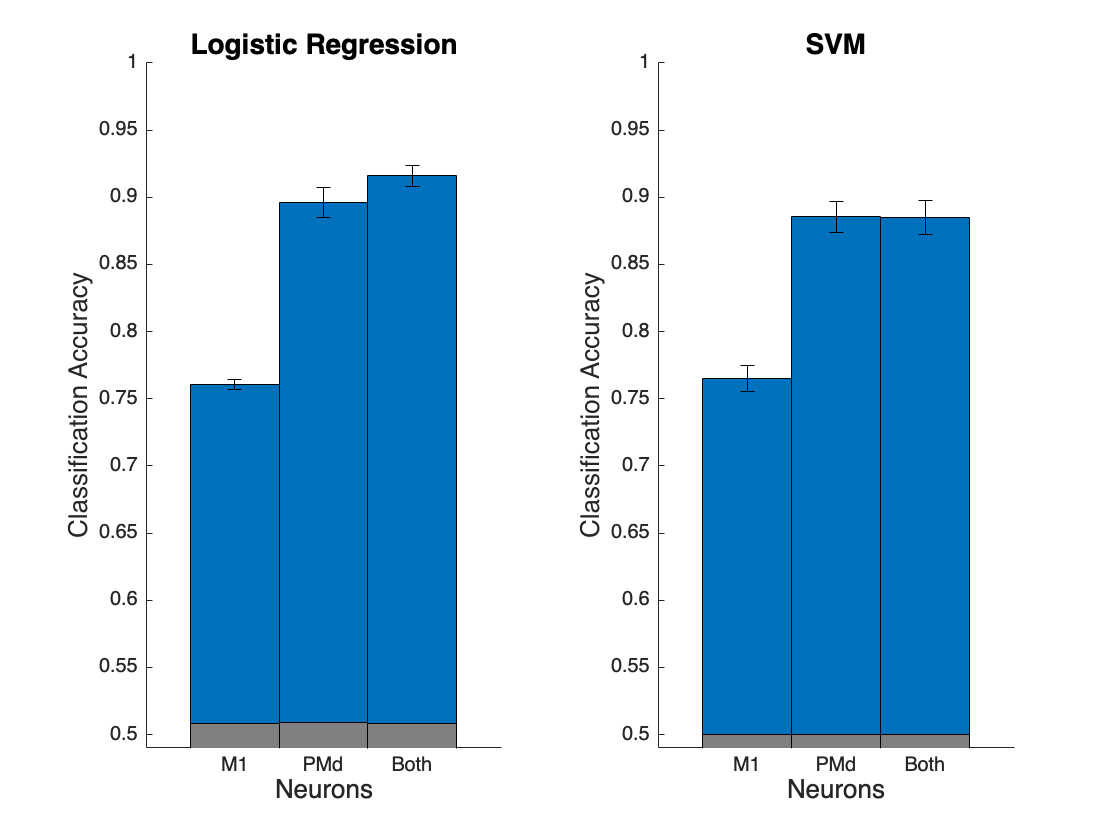

% load data
% load("classification_results.mat");

% plot data
figure;
tiledlayout(1,2);
nexttile;
hold on

acc_list = [lr_M1_acc, lr_PMd_acc, lr_all_acc];
x_list = categorical({'M1'; 'PMd'; 'Both'});
x_list = reordercats(x_list,{'M1'; 'PMd'; 'Both'});
hBar = bar(x_list, acc_list, 1);                                                    

lr_M1_sem = std(lr_M1_acc_list) / sqrt(length(lr_M1_acc_list));
lr_PMd_sem = std(lr_PMd_acc_list) / sqrt(length(lr_PMd_acc_list));
lr_all_sem = std(lr_all_acc_list) / sqrt(length(lr_all_acc_list));

e = errorbar(x_list, acc_list, [lr_M1_sem,lr_PMd_sem,lr_all_sem]);
e.Color = [0 0 0];                            
e.LineStyle = 'none';  

null_list = [mean(lr_M1_null_dist), mean(lr_PMd_null_dist), mean(lr_all_null_dist)];
bar(x_list, null_list, 1, 'FaceColor', [0.5 0.5 0.5], 'HandleVisibility', 'off');

ylim([0.49, 1]);
xlabel("Neurons", FontSize=13);
ylabel("Classification Accuracy", FontSize=13);
title("Logistic Regression", FontSize=14);

nexttile;
hold on
acc_list = [svm_M1_acc, svm_PMd_acc, svm_all_acc];
hBar = bar(x_list, acc_list, 1);       
svm_M1_sem = std(svm_M1_acc_list) / sqrt(length(svm_M1_acc_list));
svm_PMd_sem = std(svm_PMd_acc_list) / sqrt(length(svm_PMd_acc_list));
svm_all_sem = std(svm_all_acc_list) / sqrt(length(svm_all_acc_list));

e = errorbar(x_list, acc_list, [svm_M1_sem,svm_PMd_sem,svm_all_sem]);
e.Color = [0 0 0];                            
e.LineStyle = 'none';  

null_list = [mean(svm_M1_null_dist), mean(svm_PMd_null_dist), mean(svm_all_null_dist)];
bar(x_list, null_list, 1, 'FaceColor', [0.5 0.5 0.5], 'HandleVisibility', 'off');

ylim([0.49, 1]);
xlabel("Neurons", FontSize=13);
ylabel("Classification Accuracy", FontSize=13);
title("SVM", FontSize=14);

Results show that PMd neurons were better predictors in classifying whether a given trial is barrir or no barirer condition compared to M1 neurons. Also, based on shuffling the condition labels, we get chance-level classification accuracy of approximately 0.5 across all input data and classifier types. Furthermore, through repeatedly classifying randomly shuffled data, we can get the null distribution and perform one tailed t test to assess the classifier's performance. 

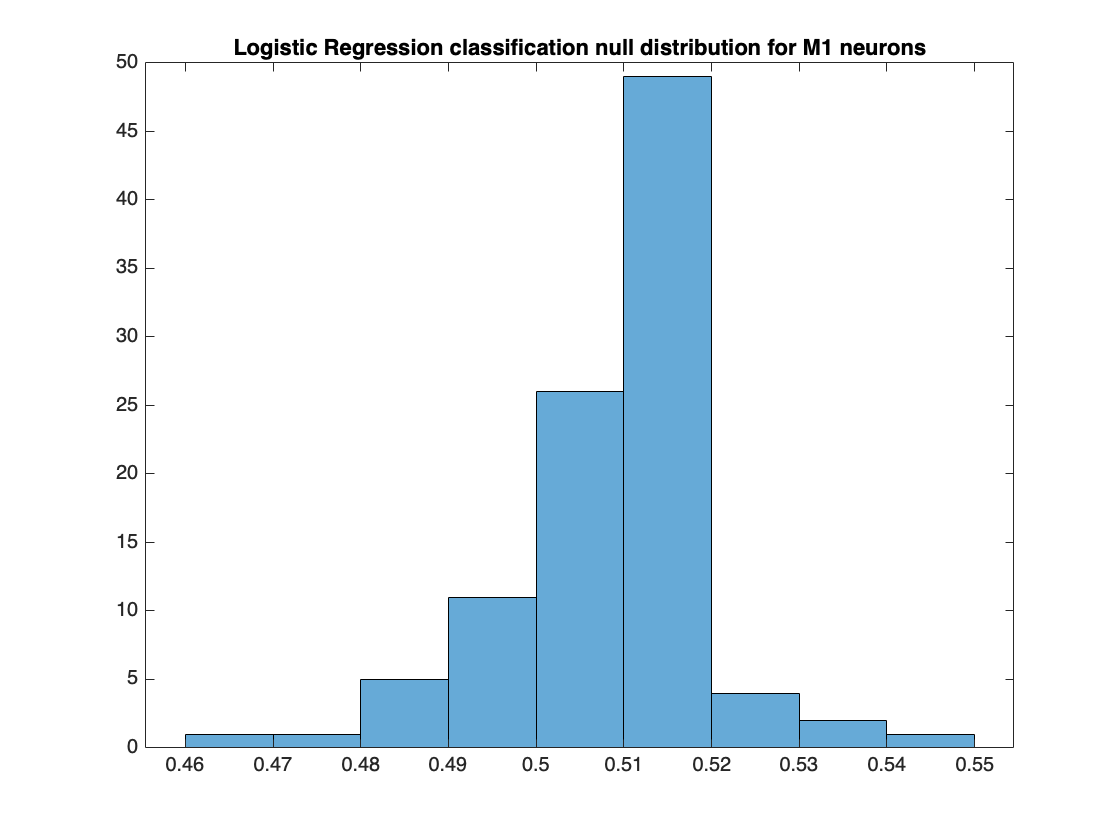

figure;
histogram(lr_M1_null_dist);
title("Logistic Regression classification null distribution for M1 neurons");

fprintf("Logistic Regression M1 p-value: %.3f", lr_M1_p_value);

Logistic Regression M1 p-value: 0.010

All of the null distributions for every condition resulted in a similar distribution as shown above, which led to same significant p value for every condition. 

In terms of classifiers, both classifiers performed similarly across various conditions. The reason why these two classifiers show comparable performances could be because the data is linear and also linearly separable. 

% now classification accuracy as a function of time for PMd neurons
time_window = 100;
time_bins = 0:50:400;

time_bins_acc_list = zeros(length(time_bins),5);
time_bins_mean_acc = zeros(length(time_bins),1);
time_bins_null_acc = zeros(length(time_bins),1);
time_bins_p_value = zeros(length(time_bins),1);

for t=1:length(time_bins)
    curr_time = time_bins(t);

    % get spike data
    data = zeros(length(selected_trials), sum(PMd_inds));
    for i=1:length(selected_trials)
        curr_trial_data = R(selected_trials(i));
        curr_onset = curr_trial_data.targetAppearsTime;
    
        for n=1:sum(PMd_inds)
            curr_n_data = curr_trial_data.unit(n);
            spike_times = curr_n_data.spikeTimes;
            nSpikes = sum(spike_times > curr_time-time_window & ...
                          spike_times < curr_time+time_window);
            data(i,n) = nSpikes;
        end
    end
    
    % run logistic regression
    [acc_list, mean_acc] = logisticRegression(data, y, 5);
    % and null distribution
    [null_acc_list, p_val] = MCStat(data, y, 100, mean_acc, "logisticRegression");
    % save
    time_bins_acc_list(t,:) = acc_list;
    time_bins_mean_acc(t) = mean_acc;
    time_bins_null_acc(t) = mean(null_acc_list);
    time_bins_p_value(t) = p_val;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


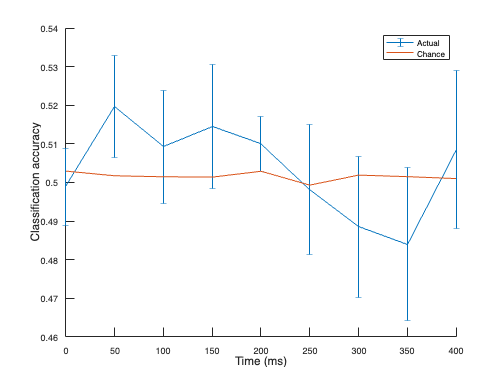

figure;
hold on

time_bins_sem = std(time_bins_acc_list,0,2) / sqrt(size(time_bins_acc_list,2));

errorbar(time_bins, time_bins_mean_acc, time_bins_sem, ...
         "DisplayName", "Actual");
plot(time_bins, time_bins_null_acc, ...
     "DisplayName", "Chance");
legend()
xlabel("Time (ms)", FontSize=13)
ylabel("Classification accuracy", FontSize=13)

Here, we are plotting classification accuracy across time points for classifier trained on PMd neurons. 

It is surprising to see that the classifier performance is no longer comparable to the previous one, where we used whole 300ms as training input. 

## Linear dimensionality reduction

- 10 fold cross validation

- error for each dimensionality (up to 50)

% separate trial-averaged data into two conditions
barrier_inds = repmat(uniq_conds==1, size(avg_data,1), 1);
no_barrier_inds = repmat(uniq_conds==2, size(avg_data,1), 1);

% reshape the data
data_2d = reshape(avg_data,[],size(avg_data,3));

% z-score
data_2d_z = zscore(data_2d);

% soft-normalization
data_2d_sn = softNormalize(data_2d, 5);

% run cross validated PCA
nFold = 10;
nComponents = 50;

% no normalization
all_cvPCA_mat = cvPCA(data_2d, nFold, nComponents);
barrier_cvPCA_mat = cvPCA(data_2d(barrier_inds,:), nFold, nComponents);
no_barrier_cvPCA_mat = cvPCA(data_2d(no_barrier_inds,:), nFold, nComponents);

% z-scored PCA
all_cvPCA_mat_z = cvPCA(data_2d_z, nFold, nComponents);
barrier_cvPCA_mat_z = cvPCA(data_2d_z(barrier_inds,:), nFold, nComponents);
no_barrier_cvPCA_mat_z = cvPCA(data_2d_z(no_barrier_inds,:), nFold, nComponents);

% soft normalization
all_cvPCA_mat_sn = cvPCA(data_2d_sn, nFold, nComponents);
barrier_cvPCA_mat_sn = cvPCA(data_2d_sn(barrier_inds,:), nFold, nComponents);
no_barrier_cvPCA_mat_sn = cvPCA(data_2d_sn(no_barrier_inds,:), nFold, nComponents);

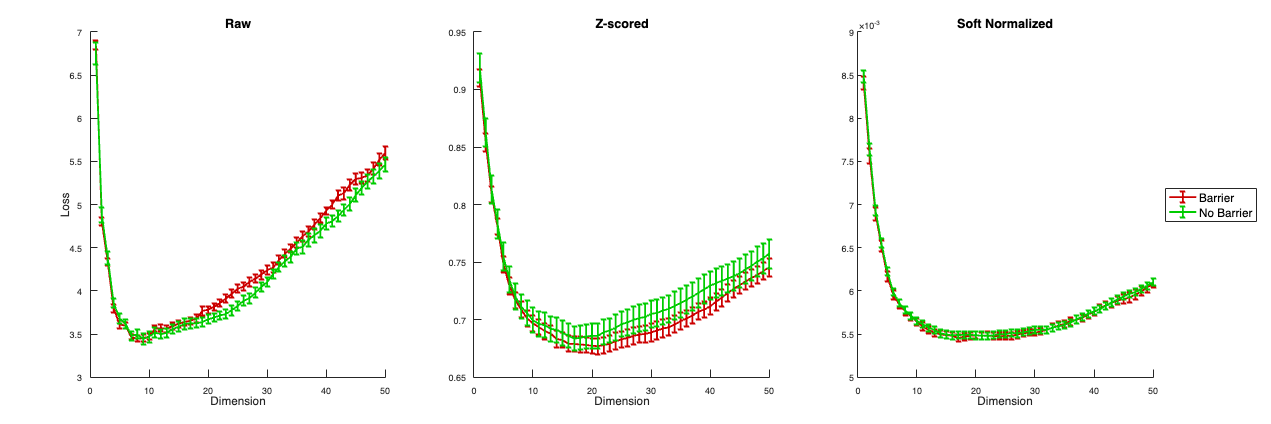

figure('Position',[0 0 1500 500]);
tiledlayout(1,3);

nexttile;
hold on

avg_barrier_cv_errs = mean(barrier_cvPCA_mat, 1);
avg_no_barrier_cv_errs = mean(no_barrier_cvPCA_mat, 1);

avg_barrier_cv_sem = std(barrier_cvPCA_mat) / sqrt(nFold);
avg_no_barrier_cv_sem = std(no_barrier_cvPCA_mat) / sqrt(nFold);

errorbar(1:nComponents, avg_barrier_cv_errs, avg_barrier_cv_sem,...
         'DisplayName', "Barrier", "Color", c_list(1,:), "LineWidth", 2)
errorbar(1:nComponents, avg_no_barrier_cv_errs, avg_no_barrier_cv_sem, ...
         'DisplayName', "No Barrier", "Color", c_list(2,:), "LineWidth", 2)
xlim([0,nComponents])
xlabel("Dimension", Fontsize=13)
ylabel("Loss", Fontsize=13)
title("Raw", FontSize=14)
hold off

nexttile;
hold on

avg_barrier_cv_errs = mean(barrier_cvPCA_mat_z, 1);
avg_no_barrier_cv_errs = mean(no_barrier_cvPCA_mat_z, 1);

avg_barrier_cv_sem = std(barrier_cvPCA_mat_z) / sqrt(nFold);
avg_no_barrier_cv_sem = std(no_barrier_cvPCA_mat_z) / sqrt(nFold);

errorbar(1:nComponents, avg_barrier_cv_errs, avg_barrier_cv_sem,...
         'DisplayName', "Barrier", "Color", c_list(1,:), "LineWidth", 2)
errorbar(1:nComponents, avg_no_barrier_cv_errs, avg_no_barrier_cv_sem, ...
         'DisplayName', "No Barrier", "Color", c_list(2,:), "LineWidth", 2)
xlim([0,nComponents])
xlabel("Dimension", Fontsize=13)
title("Z-scored", FontSize=14)
hold off

nexttile;
hold on

avg_barrier_cv_errs = mean(barrier_cvPCA_mat_sn, 1);
avg_no_barrier_cv_errs = mean(no_barrier_cvPCA_mat_sn, 1);

avg_barrier_cv_sem = std(barrier_cvPCA_mat_sn) / sqrt(nFold);
avg_no_barrier_cv_sem = std(no_barrier_cvPCA_mat_sn) / sqrt(nFold);

errorbar(1:nComponents, avg_barrier_cv_errs, avg_barrier_cv_sem,...
         'DisplayName', "Barrier", "Color", c_list(1,:), "LineWidth", 2)
errorbar(1:nComponents, avg_no_barrier_cv_errs, avg_no_barrier_cv_sem, ...
         'DisplayName', "No Barrier", "Color", c_list(2,:), "LineWidth", 2)
xlim([0,nComponents])
xlabel("Dimension", Fontsize=13)
legend('Location','eastoutside', 'FontSize',13)
title("Soft Normalized", FontSize=14)
hold off

There seems to be no statistical difference in loss curve between barrier and no barrier conditions. 

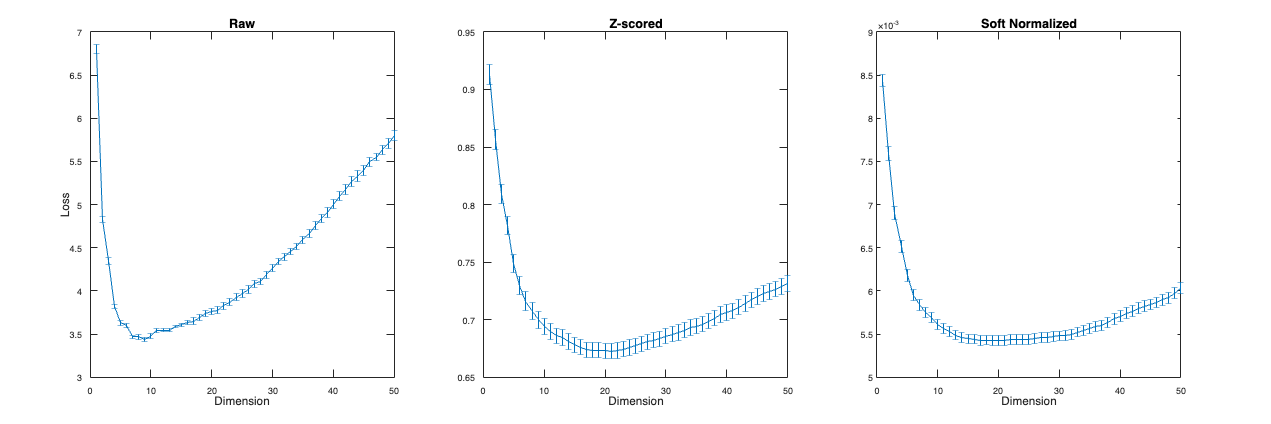

avg_errs = mean(all_cvPCA_mat,1);
avg_sem = std(all_cvPCA_mat) / sqrt(nFold);

avg_errs_z = mean(all_cvPCA_mat_z,1);
avg_sem_z = std(all_cvPCA_mat_z) / sqrt(nFold);

avg_errs_sn = mean(all_cvPCA_mat_sn,1);
avg_sem_sn = std(all_cvPCA_mat_sn) / sqrt(nFold);

figure('Position',[0 0 1500 500]);
tiledlayout(1,3);

nexttile;
errorbar(1:nComponents, avg_errs, avg_sem)
xlim([0,nComponents])
xlabel("Dimension", Fontsize=13)
ylabel("Loss", Fontsize=13)
title("Raw", FontSize=14)

nexttile;
errorbar(1:nComponents, avg_errs_z, avg_sem_z)
xlim([0,nComponents])
xlabel("Dimension", Fontsize=13)
title("Z-scored", FontSize=14)

nexttile;
errorbar(1:nComponents, avg_errs_sn, avg_sem_sn)
xlim([0,nComponents])
xlabel("Dimension", Fontsize=13)
title("Soft Normalized", FontSize=14)

Here, we plot loss curve of dimensionality to see whether different normalization schemes result in different bottlenecks. 

Using raw data (no normalization) resulted in ~8 PCs to reach bottleneck,  ~20 PCs for z-scored data, and ~22 PCs for soft normalized data. 

Normalization, in general, tends to increase the number of PCs "utilized" before reaching bottleneck, where adding more PCs leads to introducing more noise than meaningful signals. 

Also, normalization allows the data to have more evenly dispersed variability compared to raw data, which in turn leads to better utilization of PCs in terms of reconstruction. 

Therefore, it is always better to normalize the data! 

## Conclusion

We investigated the aftermath of barrier presentation in behavior and neural firing through various methods.

We were able to detect significant neural differences through machine learning classifiers, where PMd neurons showed advantage over M1 neurons on correclty classifying whether the barrier was presented or not during a given trial. 

Also, we looked at which normalization scheme resulted in best reconstruction performance through plotting loss curve of dimensionality, and soft normalization seems to effectively transform the data in a way that PCA can capture variance better across PCs. 

However, we didn't find significant difference in Fano factors as a function of time between barrier and no barrier condition, but we were able to see the temporal dynamics of motor planning in PMd, where variability of neuron decreases as monkey plans out its hand movement to the target. 